clear
load mydata1
cam = CentralCamera('focal',0.005,'resolution',[1000,1300]);

principal point not specified, setting it to centre of image plane


origin = hf

origin = 2×14 single 矩阵
  745.5847  557.6771  729.4678  732.9299  729.5181  633.5068  717.9100  613.3118  614.4866  581.0482  828.8026  735.1630  582.3765  438.2905
  411.2035  695.6019  360.6379  383.2693  551.4109  742.2540  476.9517  697.7529  695.4498  715.6491  357.4701  395.0731  674.3007  458.1467


change = hf_change

change = 2×14 single 矩阵
	1.0e+03 *

    0.9896    0.8339    0.9735    0.9777    0.9841    0.9066    0.9695    0.8854    0.8871    0.8555    1.0628    0.9801    0.8570    0.7106
    0.3309    0.6078    0.2828    0.3041    0.4628    0.6483    0.3941    0.6078    0.6056    0.6258    0.2767    0.3164    0.5875    0.3906


[r,co] = size(origin)

r = 2

co = 14

bu = ones(1,co)

bu =      1     1     1     1     1     1     1     1     1     1     1     1     1     1


k = cam.K

k =     0.0050         0  500.0000
         0    0.0050  650.0000
         0         0    1.0000


k_inv = pinv(cam.K)

k_inv = 	1.0e+05 *

    0.0020   -0.0000   -1.0000
    0.0000    0.0020   -1.3000
   -0.0000    0.0000    0.0000


inertial = k_inv*[origin;bu]*5 %原来的图在世界下的位置

inertial = 3×14 single 矩阵
	1.0e+05 *

    2.4558    0.5768    2.2947    2.3293    2.2952    1.3351    2.1791    1.1331    1.1449    0.8105    3.2880    2.3516    0.8238   -0.6171
   -2.3880    0.4560   -2.8936   -2.6673   -0.9859    0.9225   -1.7305    0.4775    0.4545    0.6565   -2.9253   -2.5493    0.2430   -1.9185
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


inertial_change = k_inv*[change;bu]*5

inertial_change = 3×14 single 矩阵
	1.0e+05 *

    4.8958    3.3393    4.7355    4.7775    4.8414    4.0659    4.6952    3.8538    3.8714    3.5552    5.6284    4.8005    3.5696    2.1064
   -3.1907   -0.4216   -3.6716   -3.4587   -1.8723   -0.0165   -2.5591   -0.4219   -0.4443   -0.2424   -3.7331   -3.3363   -0.6254   -2.5935
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000



pd = origin 

pd = 2×14 single 矩阵
  745.5847  557.6771  729.4678  732.9299  729.5181  633.5068  717.9100  613.3118  614.4866  581.0482  828.8026  735.1630  582.3765  438.2905
  411.2035  695.6019  360.6379  383.2693  551.4109  742.2540  476.9517  697.7529  695.4498  715.6491  357.4701  395.0731  674.3007  458.1467


ibvs1 = IBVS(cam, 'pstar', pd,'lambda',0.125,'P',inertial_change,'depth',5);

draw image plane in existing axes


ans =   Axes (noname) - 属性:

             XLim: [0 1000]
             YLim: [0 1300]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.3347 0.8150]
            Units: 'normalized'

  显示 所有属性


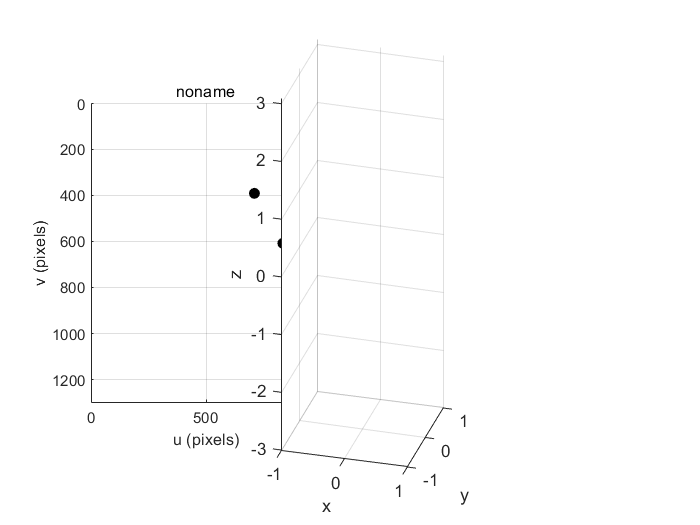

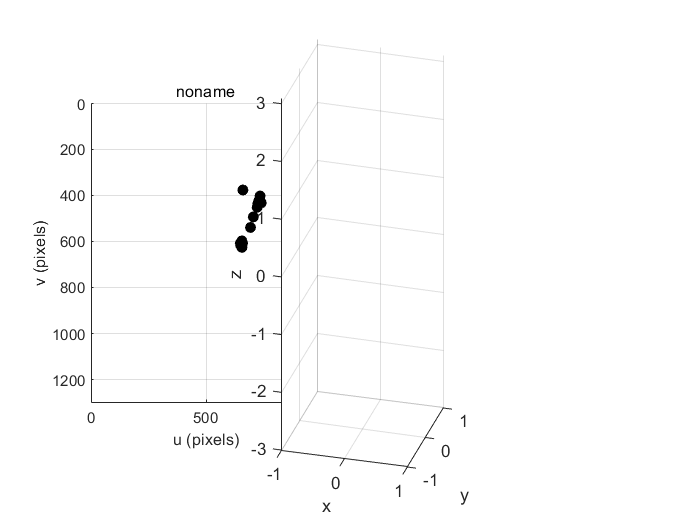

completed on iteration count


ibvs1.run(74);

ans = 1×28 single 行向量
  722.4976  451.0250  649.1985  607.4773  735.1327  402.2227  729.0357  424.0214  693.6651  538.8405  656.2712  625.4034  705.8846  493.1344  658.1183  607.7505  658.6948  606.7069  650.8071  616.2541  740.0582  431.8141  725.7565  435.6796  656.1622  597.2959  660.4358  376.2265


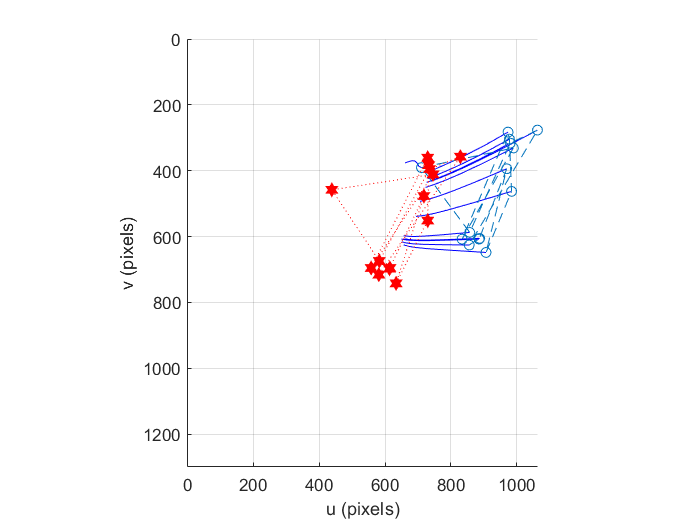

ibvs1.plot_p();

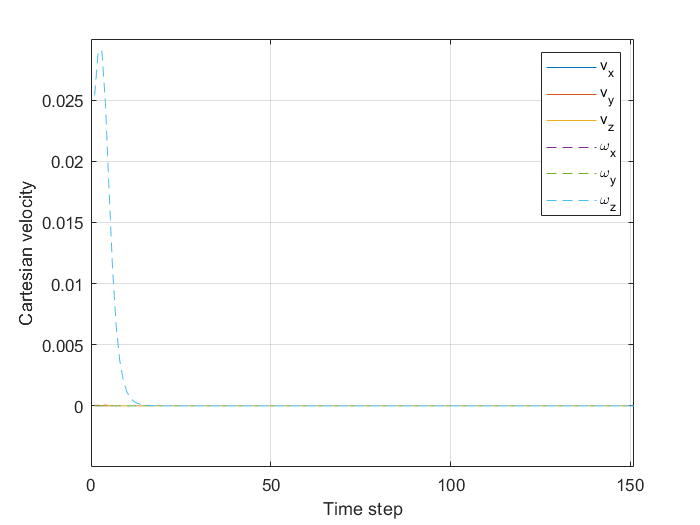

ibvs1.plot_vel();

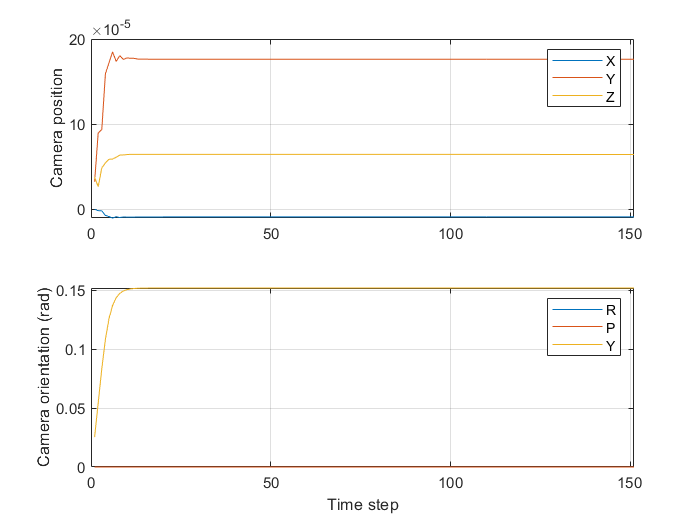

ibvs1.plot_camera();

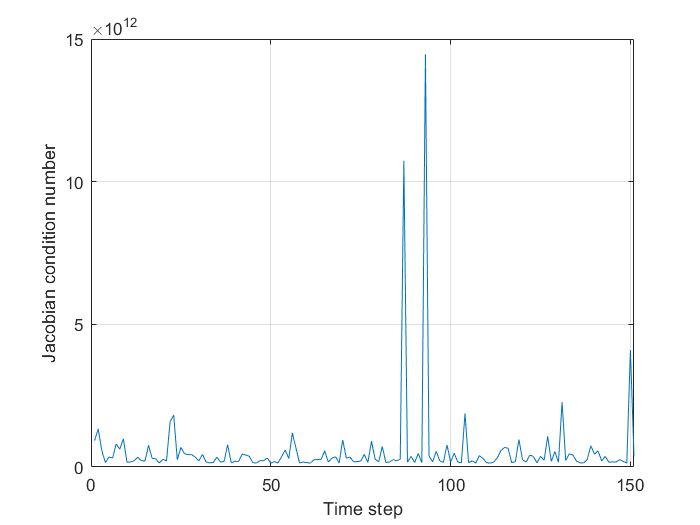

ibvs1.plot_jcond();